# Calcualtion of Inter Hamming Distance for all devices with AuNPs

For this test, we compare all combinations of the response of the same device type and compute all HD metrics for each design. We then generate plots of  Hamming Distance combining all resulting HDs.

## Read data

First extract the data from the H5 file. 

clear('files', 'results_dev1', 'results_dev2', 'results_dev3');
folder = 'G:\My Drive\PRL Group\04 Projects\2 Juan\1 OPUF ANT2 CHIP02\with AuNP\';

files{1} = 'AllDevices_Au1_Chips02_02_TM_user01_1705.smp';
files{2} = 'AllDevices_Au1_Chips02_02_TM_user02_1705.smp';
%files{3} = 'AllDevices_Au1_Chips02_02_TM_user01_1605.smp';

idx = 1;
for file = files
    filename = strcat(folder,file{1});
    struct = h52struct(filename);
    data{idx} = struct.project.measurements; 
    idx = idx+1;
end

%Data is tagged using var(1) as the device index and var(2) as the port
%index. We compare only the drop ports in the design 3 type of devices.
dev_ind   = 13:24;    % Index of the devices of interest()  
dev_port = ones(1,length(dev_ind)); dev_port(9:12) = 1;

ind_file = 1; clear dataset;
for file = files
    meas = data{ind_file} ;
    response=[];
    for i = 1:length(dev_ind)
        idx = findinproject(dev_ind(i),dev_port(i),meas);
        extract_meas = meas(idx); 
        if (iscell(extract_meas)), extract_meas = extract_meas{1};end
        m = extract_meas.spectra;
        response(:,i) = m(:,2);
        lambda = m(:,1);
    end
    dataset{ind_file} = response;
    ind_file = ind_file+1;
end

We now compute  the HD metrics for each file, the shifted datasets are computed inside of the function MultiHD

L=0.15; clear('results_dev1','results_dev2','results_dev3')
for it = 1:length(files)
    results_dev1{it} = multi_HD(lambda, dataset{it}(:,1:4 ), L);
    results_dev2{it} = multi_HD(lambda, dataset{it}(:,5:8 ), L);
    results_dev3{it} = multi_HD(lambda, dataset{it}(:,9:12), L);
    
    %% TE distance metrics
    avg(1,:) = mean([interAu1_dev1{it}.mean{1}; interAu1_dev1{it}.mean{1}] );
    avg(2,:) = mean([interAu1_dev2{it}.mean{1}; interAu1_dev2{it}.mean{1}] );
    avg(3,:) = mean([interAu1_dev3{it}.mean{1}; interAu1_dev3{it}.mean{1}] );
    
    sigma(1,:) = std([interAu1_dev1{it}.mean{1}; interAu1_dev1{it}.mean{1}] );
    sigma(2,:) = std([interAu1_dev2{it}.mean{1}; interAu1_dev2{it}.mean{1}] );
    sigma(3,:) = std([interAu1_dev3{it}.mean{1}; interAu1_dev3{it}.mean{1}] );
    
    tout= display_results(avg, sigma); disp(' ');
    it = it+1;
end

570.6± 52.5 (567.5± 54.7) 	555.1± 52.6 (535.0± 55.7) 	596.4± 148.4 (578.2± 146.4) 	 
0.424± 0.055 (0.420± 0.055) 	0.401± 0.077 (0.387± 0.081) 	0.500± 0.191 (0.491± 0.189) 	 
0.447± 0.015 (0.447± 0.015) 	0.463± 0.032 (0.452± 0.042) 	0.486± 0.082 (0.485± 0.085) 	 
 
611.4± 117.2 (605.4± 122.7) 	604.2± 87.8 (581.5± 89.0) 	598.2± 151.1 (570.6± 148.4) 	 
0.465± 0.090 (0.456± 0.095) 	0.439± 0.097 (0.430± 0.098) 	0.520± 0.221 (0.516± 0.228) 	 
0.471± 0.019 (0.467± 0.022) 	0.471± 0.032 (0.464± 0.044) 	0.522± 0.104 (0.521± 0.114) 	 
 


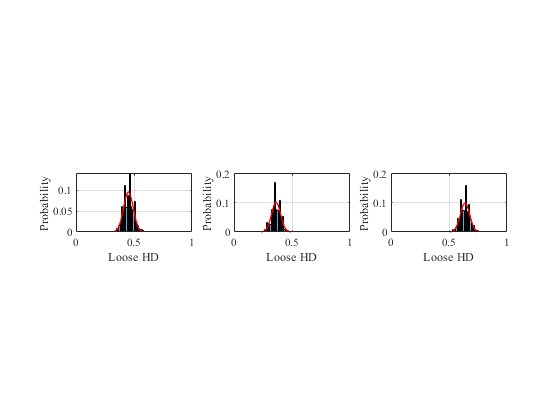

%Plot for TE response
 interAu1_dev1 = results_dev1;
 interAu1_dev2 = results_dev2;
 interAu1_dev3 = results_dev3;
 
 clear ('avg','sigma', 'average','stddev', 'tout')
 it = 1;

 for file = files
    h = figure(); clf, hold off; haxis = [0,1]; 
    metric =3; device = 1; %Loose HD
    subplot(1,3,1), 
    [xd,pd] = plotHD(interAu1_dev1{it}.HDData_s{metric}(:,device),'Loose HD',haxis); grid on;
    subplot(1,3,2), 
    [xd,pd] = plotHD(interAu1_dev2{it}.HDData_s{metric}(:,device),'Loose HD',haxis); grid on;
    subplot(1,3,3),
    [xd,pd] = plotHD(interAu1_dev3{it}.HDData_s{metric}(:,device),'Loose HD',haxis); grid on;      
 end